# Appendix: N choose N/2 and 2^N

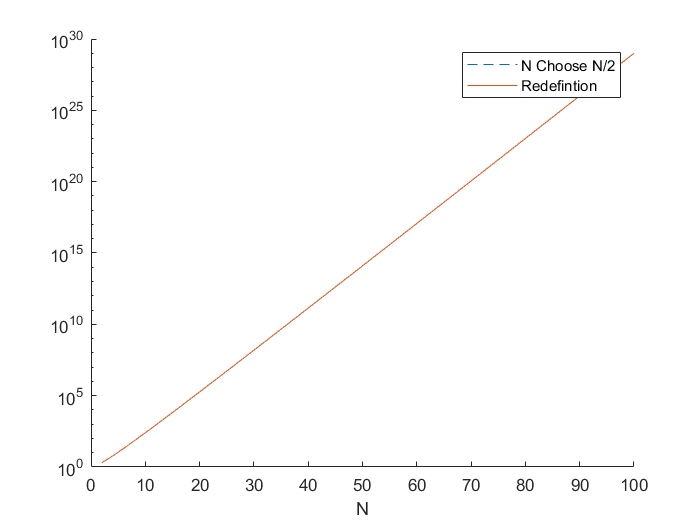

warning off
NValues = 2:2:100;

N_choose_halfNValues = zeros(1,length(NValues));
for ii = 1:length(NValues)
    N_choose_halfNValues(ii) = nchoosek(NValues(ii),NValues(ii)/2);
end

fractionTerms = zeros(1,length(NValues));
for ii = 1:length(fractionTerms)
    k = NValues(ii)/2-1;
    fractionTerms(ii) = (2*k+1)/(2*k+2);
end
reductionTerms = cumprod(fractionTerms);

redefinitionTerms = power(2,NValues).*reductionTerms;

figure
hold on
plot(NValues,N_choose_halfNValues,'LineStyle','--')
plot(NValues,redefinitionTerms)
myAxes = gca();
myAxes.YScale = 'log';
legend({'N Choose N/2','Redefintion'})
xlabel('N')

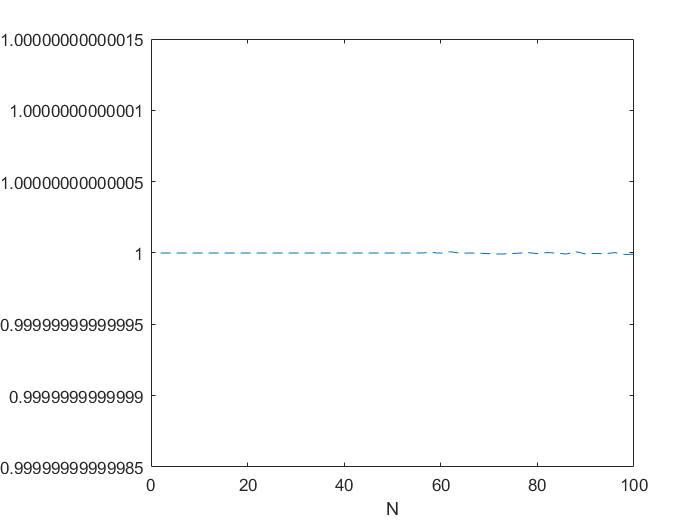


figure
plot(NValues,N_choose_halfNValues./redefinitionTerms,'LineStyle','--')
xlabel('N')





















warning on